% Clear workspace, command window, and close all figures
clear;
clc;
close all;
% Increase graphics timeout
set(0, 'DefaultFigureCreateFcn', @(fig, ~)set(fig, 'CloseRequestFcn', @(src, ~)close(src)));

# Tuneable Parameters

% Simulation parameters
params.dt = 1;  % time step (s)
num_iterations = 100; % Number of time steps
num_vehicles = 10; % Number of vehicles 

% generate_traffic_signal_states
params.red_time = 20;   % Red light duration (s)
params.yellow_time = 3.5; % Yellow light duration (s)
params.green_time = 20; % Green light duration (s)
params.d_stop_line = 300; % Stop line position (m)

% decision making
params.D_h = 150;       % Decision distance in meters
params.T_reaction = 1.0;% Reaction time in seconds
params.p_stop = 0.5;    % Probability of stopping in the dilemma zone
params.b_max = 3.0; 
params.d_0 = 0; 

% traffic light decision model
params.T_discrete = 1.0; 
params.a = 1.0;
params.D_stop = 1;  % Assuming 1 represents D_stop
params.D_go = 2;  % Assuming 2 represents D_go
params.D_undecided = 0;

% IDM parameters
params.v_desired = 15;  % desired speed (m/s)
params.a_max = 1.0;     % maximum acceleration (m/s^2)
params.b = 1.5;         % comfortable deceleration (m/s^2)
params.s0 = 2.0;        % minimum gap (m)
params.T = 1.0;         % safe time headway (s)
params.delta = 4;       % acceleration exponent

% Acceleration noise
params.n_a = 0.1;       % Bound for uniform distribution U[-params.n_a, params.n_a]




#  generate_traffic_signal_states

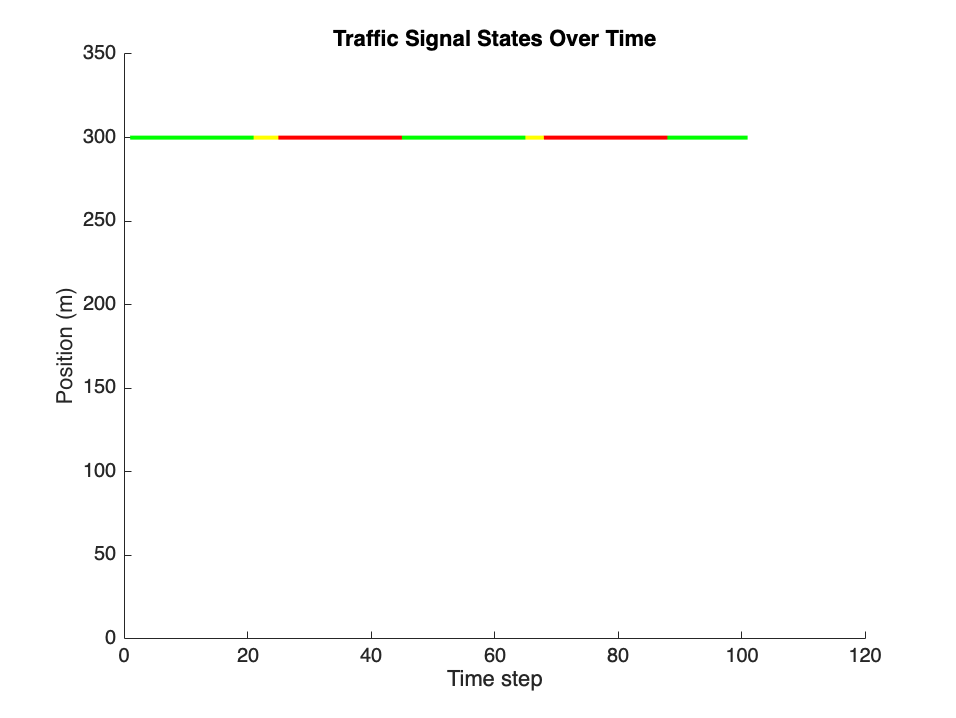

% Generate traffic signal states
S = state_transition().generate_traffic_signal_states(num_iterations, params);
% Plot traffic light state as a horizontal line at y = d_stop_line
figure(1);
hold on;

d_stop_line = params.d_stop_line;

for k = 1:num_iterations
    if S(k) == "red"
        plot([k k+1], [d_stop_line d_stop_line], 'r', 'LineWidth', 2);
    elseif S(k) == "yellow"
        plot([k k+1], [d_stop_line d_stop_line], 'y', 'LineWidth', 2);
    elseif S(k) == "green"
        plot([k k+1], [d_stop_line d_stop_line], 'g', 'LineWidth', 2);
    end
end

xlabel('Time step');
ylabel('Position (m)');
title('Traffic Signal States Over Time');
ylim([0 d_stop_line + 50]);
hold off;

# elapsed_yellow_time

% 在主循环中
for k = 1:num_iterations
    % 计算当前时间步的 T_elapsed
    T_elapsed = StateTransition.update_elapsed_time(k, num_vehicles, S(1:k), params);
    
    % 计算下一个时间步的 T_elapsed
    T_elapsed_next = StateTransition.calculate_T_elapsed_next(T_elapsed(k,:), S(k), S(k+1), params);
    
    % 调用决策函数
    D_next = StateTransition.decision_making(d_k, d_next, v_k, v_next, S(k), S(k+1), T_elapsed(k,:), T_elapsed_next, D_k, num_vehicles, params);
    
    % 更新其他状态变量
    % ...
end

disp('elapsed_yellow_time');

elapsed_yellow_time


disp(T_elapsed);

         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0 

# IDM

% Initial conditions
d = zeros(num_iterations, num_vehicles);
v = zeros(num_iterations, num_vehicles);
a_IDM_next = zeros(num_iterations, num_vehicles);
s = 20 * ones(1, num_vehicles);  % initial gap to the leading vehicle (m)

% Set initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions (m)
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds (m/s)



% Simulate over time
for k = 1:num_iterations-1
    for i = 1:num_vehicles
        if i == 1
            % Leading vehicle dynamics (no vehicle in front)
            delta_v = v(k, i); % Speed difference to leading vehicle, 0 for first vehicle
            s_i = Inf; % Infinite gap for the leading vehicle
        else
            % Following vehicles
            delta_v = v(k, i-1) - v(k, i);
            s_i = d(k, i-1) - d(k, i);
            if s_i <= 0
                s_i = 0.1; % Avoid division by zero or negative gap
            end
        end

         % Ensure delta_v is within reasonable bounds
        delta_v = max(min(delta_v, params.v_desired), -params.v_desired);

        a_IDM_next(k, i) = state_transition().intelligent_driver_model(v(k, i), delta_v, s_i, params);
        a_decision_next = state_transition().traffic_light_decision_model();

        % Update velocity and position using state_transition function
        current_state = [d(k, i), v(k, i), a_IDM_next(k, i), 0, 0]; % Assuming D and lane are not used in the current context
        next_state = state_transition().nextState(current_state, params);
        
        % Extract next state's position and velocity
        d(k+1, i) = next_state(1);
        v(k+1, i) = next_state(2);

        % Ensure velocities and positions are within reasonable bounds
        v(k+1, i) = max(min(v(k+1, i), 2 * params.v_desired), 0); % Speed cannot be negative
        d(k+1, i) = max(d(k+1, i), 0); % Position cannot be negative

        % Check for invalid values
        if isnan(d(k+1, i)) || isnan(v(k+1, i)) || isinf(d(k+1, i)) || isinf(v(k+1, i))
            error('Invalid value detected at iteration %d for vehicle %d.', k, i);
        end
    end
end

Not enough input arguments.

Error in state_transition>traffic_light_decision_model (line 236)
    T_discrete = params.T_discrete;  % Discretization time interval (1 s)

% Display results
disp('Accelerations (a_IDM_next):');
disp(a_IDM_next);
disp('Velocities (v):');
disp(v);
disp('Positions (d):');
disp(d);